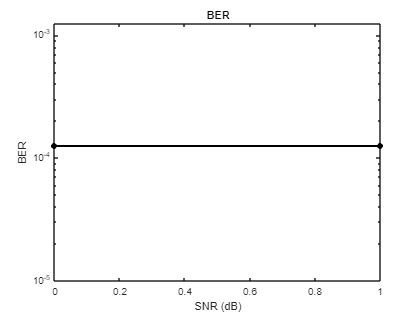

clear
clc
% System Parameters 
m = 4; % Modulation order - VARIABLE!!!
k = log2(m); % Bits per Symbol
snr = 0:20; % SNR vector - !
fc = 2.4e9; % Carrier frequency [Hz] - VARIABLE!!
lambda = 3e8/fc; % Wavelength
k_w = (2*pi)/lambda; % Wavenumber
n_sym = 1000; % number of test symbols - !
ts = 1e-5; % Symbol period - VARIABLE!
r_sym = 1/ts; % Symbol rate
b = r_sym*k; % Signal bandwidth

% Antenna Layout and Parameters
p_in = 1; % Input Power [W] - !
n_t = 4; % Number of transmitter antennas
n_r = 4; % Number of receiver antennas
da = 0.5*lambda; % Antenna spacing

for ntr = 1:n_t
    z_tr = (ntr-1)*da;
    tx_pos(ntr,:) = [58 10 5+z_tr];
end

for nre = 1:n_r
    z_re = (nre-1)*da;
    rx_pos(nre,:) = [-30 -10 -5+z_re];
end
%RIS Dimensions
n_rows = 4; 
n_columns = 4;

nris = n_rows*n_columns;
dris = 0.5*lambda;
% RIS Position
ris_pos = zeros(nris,3); % Cause 3D
idx = 1;
for row = 1:n_rows
    for col = 1:n_columns
        y = (col-1)*dris;
        z = (row-1)*dris;
        ris_pos(idx,:) = [0,y,z];
        idx = idx + 1;
    end
end
for ris_no = 1:nris
    for rx_no = 1:n_r
        dist_risue(ris_no,rx_no) = norm((rx_pos(n_r)-ris_pos(ris_no,:))); % Euclidean distance between the user andthe n-th RIS element 
        v(ris_no,rx_no) = acos(rx_pos(rx_no,1)/dist_risue(ris_no,rx_no)); % Angle of departure
    end
    for tx_no = 1:n_t
        dist_txris(ris_no,tx_no) = norm(ris_pos(ris_no,:)-tx_pos(n_r));
    end
    dist_ris(ris_no) = norm((ris_pos(ris_no,:)-(-0.1)));
    z_imp(ris_no) = (sinc(k_w*(dist_ris(ris_no)-dist_ris(1))));
end

% Correlation (impedance) matrix
z_grid = reshape(z_imp,n_rows,n_columns);
% 
% 
% path loss calculation
dist_tot = dist_txris+dist_risue;
p_l = p_in*(((lambda/4)^2)./((4*pi)*dist_tot.^2));

%init
len = length(snr);
ber = zeros(1,len);

% Simulation

for i = 1:len
    snr_value = 10.^(snr(i)/10);
    ea = 1; % Transmitter element power
    es = ea*n_t; % Total transmitted power
    sigma_n = es/snr_value; % noise power

    threshold_snr = 15; %Snr threshold in dB
    p_sig = 0;
   
    rng(2,"twister")
    %H = sqrt(0.5)*(randn(n_r,n_t)+1j*randn(n_r,n_t)); % Rayleigh MIMO channel
    H = channel_ris(n_r,n_t,nris,z_imp/lambda); %RIS channel
    ZF_F = H'*inv(H*H'); %Precoding Matrix
    beta_zf = sqrt(es/norm(ZF_F,"fro").^2); 
    F_ZF = beta_zf*ZF_F; %Normalized Precoding Matrix
    num_outages(i) = 0;
    for sym_index = 1:n_sym
        tx_data = randi([0 m-1],n_t,1); % data generation
        tx_sig = pskmod(tx_data,4); % Modulation
        tx_zf = F_ZF*tx_sig; % Precoding
        n = sqrt(sigma_n/2)*(randn(n_r,2)+j*randn(n_r,2)); %Noise
        y_zf = H*tx_zf+n(:,2);
        r_zf = 1/beta_zf*y_zf; %Received signal
        rec_data_zf = pskdemod(r_zf,m); % Received data
        [err ratio] = biterr(rec_data_zf,tx_data); %BER
        ber(1,i) = ber(1,i)+ratio; 
        p_sig = p_sig + norm(F_ZF)^2; % Received signal power
        p_n = p_sig/(10^(snr(i)/10)); %Noise power
        received_snr(i) = (mean(mean(abs(H*es).^2/p_n))); %Received SNR
        received_snr_db = 10*log10((mean(mean(abs(H*es).^2/p_n))));
        if received_snr_db< 10
             num_outages = num_outages +1;
        end
        r(i) = b*log2(1+received_snr(i)); %Data rate
    end
end
ber=ber/n_sym;
p_o_mimo = num_outages/(n_sym*len); %Outage Probability

figure
semilogy(snr,ber,'LineWidth',2,'Color',[0 0 0],'Marker','*');
title("BER")
xlabel('SNR (dB)')
ylabel('BER')

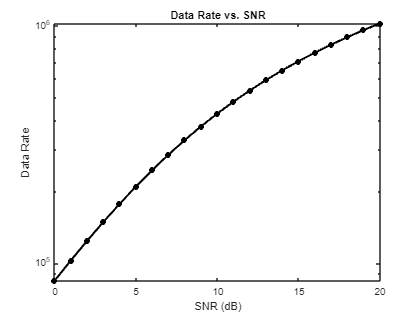


figure
semilogy(snr,r,'LineWidth',2,'Color',[0 0 0],'Marker','*');
title('Data Rate vs. SNR')
xlabel('SNR (dB)')
ylabel('Data Rate')